# Demo file for creating HHs using MatHH

This demo file shows basic functionality of the MatHH framework, through a set of examples. In particular, we use the framework to create Rule-based Selection Hyper-heuristic (RBSHH) models. 

## Cleanup:

clc
clear
close all

## Balanced Partition Problem

Package loading: 

addpath('..\..\src\') % Adds common functionality (HH models)
addpath(genpath('..\extended\Utils')) % Adds common utilities package
addpath(genpath('..\extended\Domains\JSSP')) % Adds JSSP package (required for default mode)

Load Balanced Partition package:

addpath(genpath('..\extended\Domains\BP')) % Problem domain model
addpath('..\extended\Domains\') % Common abstract classes 

### HH creation and usage

We can create an 'empty' HH by invoking its constructor:

HH1 = ruleBasedSelectionHH()

HH1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

This uses default parameter values for the model. Additionally, we can use a structure for defining specific properties. 

***Recommended usage***

Define a structure with the properties of the RBSHH and pass it as an argument. The following fields are currently supported (default values given in parentheses):

- nbRules             (2)     - Number of rules   

- targetProblemHandle (@JSSP) - Function handle for the COP that will be tackled

- selectedFeatures    (All)   - Vector with the IDs of the features that will be used by the model    

- selectedSolvers     (All)   - Vector with the IDs of the solvers that will be used by the model  

Since we are interested (at this point) in developing a RBSHH model for the Balanced Partition (BP) problem, we need to change the default problem domain. Additionally, we can create a model with the default number of rules (2), and with an extended set of rules (5), to compare how performance changes. So, we have that:

customParams = struct('targetProblemHandle', @BP) % Changes default problem domain

customParams = struct with fields:
    targetProblemHandle: @BP


HH2 = ruleBasedSelectionHH(customParams) % Create HH model with custom parameters

HH2 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev


customParams = struct('targetProblemHandle', @BP, 'nbRules', 5) % Changes default problem domain and number of rules

customParams = struct with fields:
    targetProblemHandle: @BP
                nbRules: 5


HH3 = ruleBasedSelectionHH(customParams) % Create HH model with custom parameters

HH3 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

Since we have a couple HHs, we can analyze them, e.g. to see the kind of actions they will take. To do so we can benefit from the *plotZones* method.

The *plotZones* method has the following optional inputs (default values given in parentheses):

- points (0:0.01:1) - Vector with the points that will be evaluated (per dimension)

- isEuclidean (true) - Flag indicating if Euclidean distance will be used

- selectedFeatures (1:2) - Vector with two elements containing the IDs of the features (columns) to use when plotting

- doRules (false) - Flag indicating if the rules should be plotted as well

**Note**: This method returns a vector with the relative area covered by each solver.

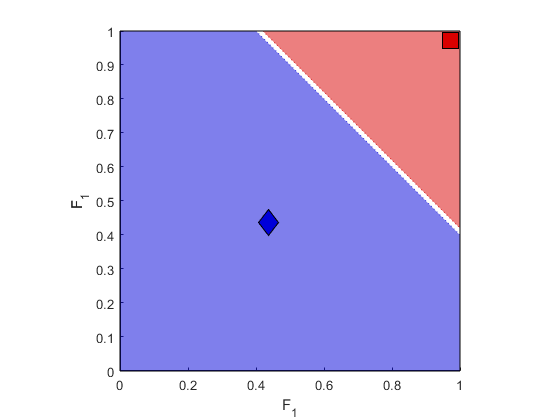

ans =     0.1682    0.8200


customGridPoints = 0:0.02:1; % Define the points of the custom grid
isEucFlag = true; % Sets usage of Euclidean distance 
featuresToPlot = [1 1]; % Defines twice the same feature, since we only have one
doRulesFlag = true; % Requests that the location of rules be plotted

HH2.plotZones(customGridPoints,isEucFlag,featuresToPlot,doRulesFlag) % Zones of one model

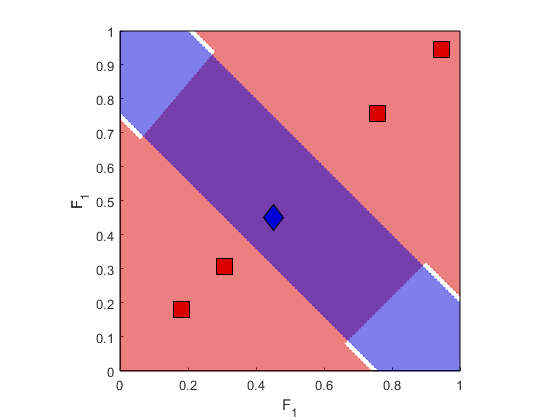

ans =     0.8708    0.3912


HH3.plotZones(customGridPoints,isEucFlag,featuresToPlot,doRulesFlag) % Zones of another model

We can also replace the randomly generated model by a user-defined one:

newModel = [0.2 1; 0.3 2]; % New selector for the RBSHH
HH2.setModel(newModel) % Imposes new selector on the model
disp(HH2) % Shows RBSHH to validate the changes

Displaying information about the New HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	2
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )

Current model:
    RuleID    F1     HeuristicID
    ______    ___    ___________

      1       0.2         1     
      2       0.3         2     



We need some instances to test our models. So, we can use existing instances from the provided datasets:

instanceDataset = '..\..\..\BaseInstances\BalancedPartition\files\mat\Random\5Elements\2Bits\instanceDataset.mat'

instanceDataset = '..\..\..\BaseInstances\BalancedPartition\files\mat\Random\5Elements\2Bits\instanceDataset.mat'

fileData = load(instanceDataset); % Loads the dataset
allInstancesSmall = fileData.instanceDataset; % Extracts instances from dataset

Conversely, we can use the *loadInstanceSet* method of the *BP* class to make things easier:

% For 25 elements with 4 bits:
allInstancesBig = BP.loadInstanceSet('rand25E4B'); % Use built-in loader

To solve the dataset we can use the *solveInstanceSet* method of the HH, which returns the solved instances (original ones are preserved):

solvedInstances = HH2.solveInstanceSet(allInstancesBig(1:5)) % Solves an instance subset and stores a solved copy

solvedInstances = 1×5 cell array
    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}


solvedInstancesHH3 = HH3.solveInstanceSet(allInstancesBig(1:5)) % Solves an instance subset and stores a solved copy

solvedInstancesHH3 = 1×5 cell array
    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}


We can analyze the actions taken by the HH in several ways. For example, we can generate plots showing the action (heuristic) chosen at each step when solving a single instance:

figure
subplot(2,1,1), HH2.plotSolverUsage(1)

ans =   Axes with properties:

             XLim: [0 16]
             YLim: [1 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


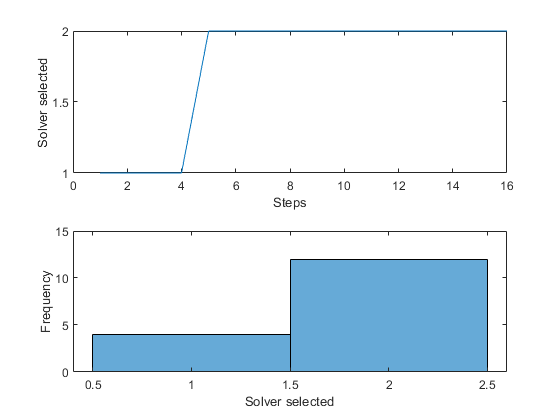

ans =   Axes with properties:

             XLim: [0.4000 2.6000]
             YLim: [0 15]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


subplot(2,1,2), HH2.plotSolverUsageDistribution(1)


figure
subplot(2,1,1), HH3.plotSolverUsage(1)

ans =   Axes with properties:

             XLim: [0 14]
             YLim: [1 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


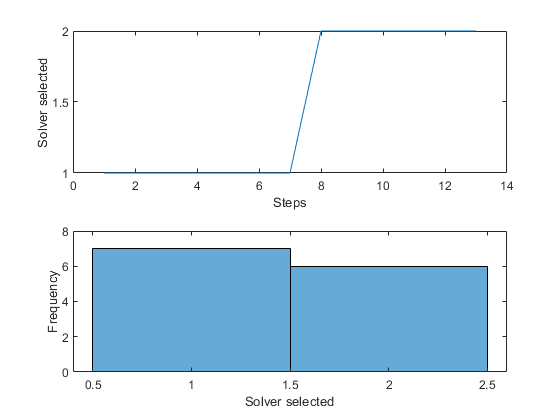

ans =   Axes with properties:

             XLim: [0.4000 2.6000]
             YLim: [0 8]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


subplot(2,1,2), HH3.plotSolverUsageDistribution(1)

We can also plot the distribution of feature values for a given dataset using the *plotFeatureMap *method:

- instances: Dataset that will be analyzed

- opMode: Kind of features to show. Can be: 'initial', 'full', 'final', or a scalar indicating a solution step ID.

- optParams: Optional parameter. A structure indicating additional plotting parameters (nbBins, valMin, valMax, features)

- trackFlag: Flag for indicating if the feature values for a given instance will be tracked (connected) to highlight them.

- instID: The ID of the instance that will be tracked.

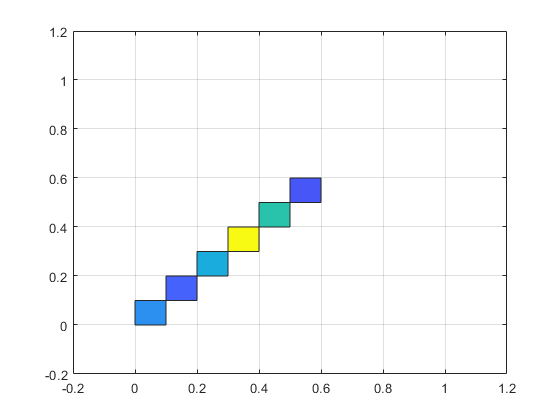

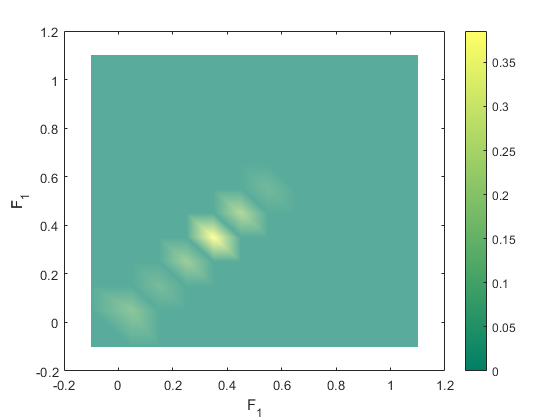

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties


reducedDataset = allInstancesBig(1:5);
optParams = struct('features',[1 1]);
HH2.plotFeatureMap(reducedDataset,'full', optParams,false) % Only plots (no tracking)

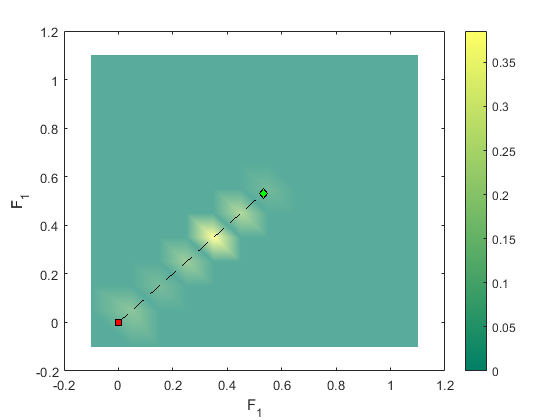

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties


HH2.plotFeatureMap(reducedDataset,'full', optParams,true,3) % Plots and tracks instance 3

### **Defining a BP instance from scratch**

We can also create BP instances from scratch. So, let us create custom BP instances, for the following sets of items:

- items  = [10 1 1 1 1 1 1 1 1 1 1 1 1]

- items  = [10 9 8 1 1 2 2 1 1 1 1 1 1]

- items  = [10 3 4 2 10 10 1 1 1 1 1 1 1]

To do so, we need to use the **BPInstance** class. 

An instance can be created from the following sources: 

- Numeric vector. User provides an array of values and an ID for the instance. 

- Vector of BPItem objects. Same as before but using an array of BPItem objects as the first argument.

- Another BPInstance. In this case the user must only provide an already created object and the method returns a deep copy of such an instance.

In this case, we will use the first option, and provide consecutive IDs for each instance:

items  = [10 1 1 1 1 1 1 1 1 1 1 1 1];
i1 = BPInstance(items, 1);
items  = [10 9 8 1 1 2 2 1 1 1 1 1 1];
i2 = BPInstance(items, 2);
items  = [10 3 4 2 10 10 1 1 1 1 1 1 1];
i3 = BPInstance(items, 3);

Now, we just need to merge these instances into a single dataset:

customInstances = {i1, i2, i3}

customInstances = 1×3 cell array
    {1×1 BPInstance}    {1×1 BPInstance}    {1×1 BPInstance}


And we can proceed to solve the dataset with the existing HHs:

solvedCI_HH2 = HH2.solveInstanceSet(customInstances);
solvedCI_HH3 = HH3.solveInstanceSet(customInstances);

Each instance contains a *solution* property. In this case it contains a *BPSolution* object with the final form of the two subsets. Moreover, it has a *getSolutionPerformanceMetric* property that returns the quality of the solution (Q):

nbInstances = length(customInstances);
Q_HH2 = nan(1,nbInstances); % Pre-allocate
Q_HH3 = nan(1,nbInstances); % Pre-allocate
for idx = 1 : nbInstances % Sweep instances
    Q_HH2(idx) = solvedCI_HH2{idx}.solution.getSolutionPerformanceMetric; % Performance for current instance with HH2
    Q_HH3(idx) = solvedCI_HH3{idx}.solution.getSolutionPerformanceMetric; % Performance for current instance with HH3
end
allPerformanceMetrics = [Q_HH2;Q_HH3] % Accumulate and store

allPerformanceMetrics =      0     1     0
     0     1     0



solvedCI_HH2{1}.solution.sets(1) % Display set information

ans =   BPSet with properties:

      elements: [1×11 BPItem]
            ID: 1
          load: 11
    nbElements: 11


[solvedCI_HH2{1}.solution.sets(1).elements.load] % Load of each element in first subset

ans =      1     1     1     1     1     1     1     1     1     1     1


[solvedCI_HH2{1}.solution.sets(2).elements.load] % Load of each element in second subset

ans =     10     1



solvedCI_HH3{1}.solution.sets(1)

ans =   BPSet with properties:

      elements: [1×11 BPItem]
            ID: 1
          load: 11
    nbElements: 11


[solvedCI_HH3{1}.solution.sets(1).elements.load]

ans =      1     1     1     1     1     1     1     1     1     1     1


[solvedCI_HH3{1}.solution.sets(2).elements.load]

ans =     10     1


By this point it is worth commenting that we can also create 'fake' HHs, i.e. HHs that target a single heuristic. This, in fact, is equivalent to using said heuristic all the time:

customParams = struct('targetProblemHandle', @BP, 'nbRules', 1)

customParams = struct with fields:
    targetProblemHandle: @BP
                nbRules: 1


H1 = ruleBasedSelectionHH(customParams);
H1.setModel([0.5 1]) % Create model with a single rule, so that all actions target the same solver
disp(H1)

Displaying information about the New HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	1
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )

Current model:
    RuleID    F1     HeuristicID
    ______    ___    ___________

      1       0.5         1     



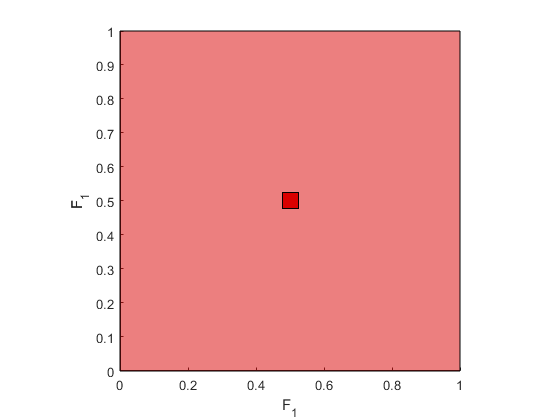

ans = 1.0000

H1.plotZones(customGridPoints,isEucFlag,featuresToPlot,doRulesFlag)


H2 = ruleBasedSelectionHH(customParams);
H2.setModel([0.5 2])
disp(H2)

Displaying information about the New HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	1
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )

Current model:
    RuleID    F1     HeuristicID
    ______    ___    ___________

      1       0.5         2     



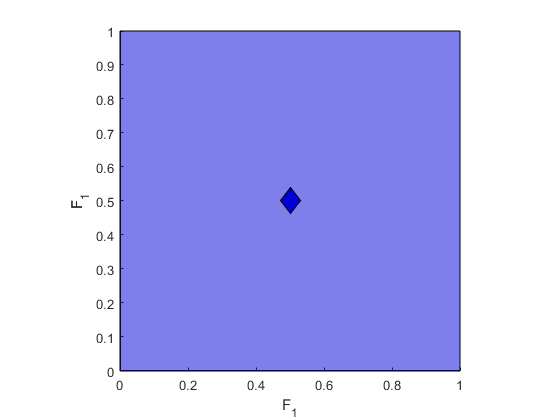

ans =        NaN    1.0000


H2.plotZones(customGridPoints,isEucFlag,featuresToPlot,doRulesFlag)

And we can use the heuristics to solve the custom dataset so that we can compare performance:

solvedCI_H1 = H1.solveInstanceSet(customInstances);
solvedCI_H2 = H2.solveInstanceSet(customInstances);

Q_H1 = nan(1,nbInstances);
Q_H2 = nan(1,nbInstances);
for idx = 1 : nbInstances
    Q_H1(idx) = solvedCI_H1{idx}.solution.getSolutionPerformanceMetric;
    Q_H2(idx) = solvedCI_H2{idx}.solution.getSolutionPerformanceMetric;
end
allPerformanceMetricsHeur = [Q_H1;Q_H2];
perfComparison = [allPerformanceMetrics;allPerformanceMetricsHeur]

perfComparison =      0     1     0
     0     1     0
     0    15    14
     0     1     6


### **Training a HH**

MatHH mainly uses the Unified Particle Swarm Optimization (UPSO) algorithm for training HH models. This algorithm has several tunable parameters with default values. Some work has been carried out for allowing the MAP-Elites training method, but this remains experimental. The training is carried out with the *train* method, which has two optional arguments:

- method ('UPSO'): The training method to use. Can be either 'UPSO' or 'MAP-Elites'.

- trainParams: Structure with the training parameters. Can contain the following fields:

-     visualMode (false): Flag for showing fitness evolution

-     verboseMode (true): Flag for showing output in command window

-     populationSize (15): Number of search agents to use

-     maxIter (100): Maximum number of iterations to train for

-     maxStagIter (maxIter): Maximum number of iterations before activating a stagnation stop flag

-     selfConf (2.00): Self-confidence constant (UPSO parameter)

-     globalConf (2.50): Global-confidence constant (UPSO parameter)

-     unifyFactor (0.25): Unification factor (UPSO parameter)

Also, we need to load the instances that will be used for training into the *trainingInstances* property. So, let us train HH3:

HH3.trainingInstances = reducedDataset;
trainParams = struct('maxIter', 10)

trainParams = struct with fields:
    maxIter: 10


HH3.train('upso', trainParams)


[  09:53:22] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 10
          maxStagIter: 10
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 10
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 20
         ... Initialisation completed!

[Step     2] Global be

ans =     0.2024
         0
    0.1452
    0.7493
         0
    1.0000
    1.3183
    1.1543
    1.7849
    1.8126


disp(HH3)

Displaying information about the Trained HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 5 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 15
           maxIter: 10
       maxStagIter: 10
          selfConf: 2
        globalConf: 2.5000
       unifyFactor: 0.2500

	Performance achieved:	10.00
	Time taken:	100.54
	Evaluations taken:	160
	Iterations performed:	10
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	5
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )

Current model:
    RuleID      F1       HeuristicID
    ______    _______    ___________

      1       0.20242         1     
      2             0         1     
      3   

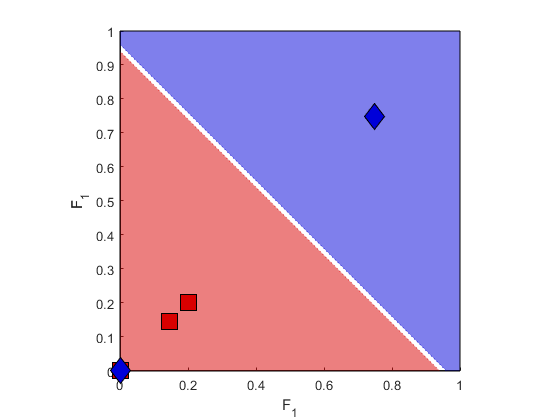

ans =     0.4418    0.5392


HH3.plotZones(customGridPoints,isEucFlag,featuresToPlot,doRulesFlag)

 Let us compare the performance before and after training:

solvedInstancesHH3New = HH3.solveInstanceSet(reducedDataset);
nbInstances = length(reducedDataset);
perfHH3Train = nan(2,nbInstances);
for idx = 1 : nbInstances
    perfHH3Train(1,idx) = solvedInstancesHH3{idx}.solution.getSolutionPerformanceMetric; % old model
    perfHH3Train(2,idx) = solvedInstancesHH3New{idx}.solution.getSolutionPerformanceMetric; % trained model
end
perfHH3Train % per instance performance

perfHH3Train =      6     4     5     3     6
     2     4     1     3     0


mean(perfHH3Train,2) % mean performance

ans =     4.8000
    2.0000


## **Job Shop Scheduling Problem**

Since the JSSP domain is the default domain, we have already loaded it during the previous examples. So, we can move on to testing RBSHHs.

### Load instances for testing

% ------ First set of training instances (5x5)
instanceDataset = '..\..\..\BaseInstances\JobShopScheduling\files\mat\Instances\E02\instanceDataset.mat';
load(instanceDataset);
trainInstances1 = num2cell(allInstances); % Stores instances as cell array
fprintf('Loaded %d instances\n', length(trainInstances1))

Loaded 30 instances



% ------ Second set of training instances (15x15)
instanceDataset = '..\..\..\BaseInstances\JobShopScheduling\files\mat\Instances\E01\instanceDataset.mat';
load(instanceDataset);
trainInstances2 = num2cell(allInstances); % Stores as cell array
fprintf('Loaded %d instances\n', length(trainInstances2))

Loaded 30 instances


### Creation of RBSHHs

nbRules = 3;
selectedFeatures = 1:2;
propsHH = struct('nbRules',nbRules,'selectedFeatures',selectedFeatures);
HH1 = ruleBasedSelectionHH(propsHH);
disp(HH1)

Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	3
	Usable features:	2 (  1  2  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID       F1          F2       HeuristicID
    ______    ________    ________    ___________

      1        0.17119     0.27692         3     
      2        0.70605    0.046171         2     
      3       0.031833    0.097132         3     




nbRules = 7;
selectedFeatures = 1:2;
propsHH = struct('nbRules',nbRules,'selectedFeatures',selectedFeatures);
HH2 = ruleBasedSelectionHH(propsHH);
disp(HH2)

Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	7
	Usable features:	2 (  1  2  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID      F1         F2       HeuristicID
    ______    _______    _______    ___________

      1       0.76552    0.75469         4     
      2        0.7952    0.27603         3     
      3       0.18687     0.6797         2     
      4       0.48976     0.6551         4     
      5       0.44559    0.16261         1     
      6       0.64631      0.119         2     
      


nbRules = 5;
selectedFeatures = 1:2;
selectedSolvers = 2:3;
propsHH = struct('nbRules',nbRules,'selectedFeatures',selectedFeatures,...
    'selectedSolvers',selectedSolvers);
HH3 = ruleBasedSelectionHH(propsHH);
disp(HH3)

Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	5
	Usable features:	2 (  1  2  )
	Usable solvers:	2 (  2  3  )

Current model:
    RuleID      F1         F2       HeuristicID
    ______    _______    _______    ___________

      1        0.2551    0.54722         3     
      2       0.50596    0.13862         2     
      3       0.69908    0.14929         3     
      4        0.8909    0.25751         2     
      5       0.95929    0.84072         3     



### Training the models

% Instance assignment:
HH1.trainingInstances = trainInstances1;
HH2.trainingInstances = trainInstances1;
HH3.trainingInstances = trainInstances1;

% Parameters:
trainingMethod = 'UPSO';
maxIter = 10;
populationSize = 20;
selfConf = 2.1;
globalConf = 2.1;
unifyFactor = 0.5;
visualMode = false;
trainingParams = struct('maxIter',maxIter,'populationSize',populationSize,...
    'selfConf',selfConf,'globalConf',globalConf,'unifyFactor',unifyFactor,...
    'visualMode',visualMode);

% Process:
HH1.train(trainingMethod, trainingParams);


[  11:14:03] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 20
              maxIter: 10
          maxStagIter: 10
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 9
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.425e+04
         ... Initialisation completed!

[Step     2

HH2.train(trainingMethod, trainingParams);


[  11:17:09] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 20
              maxIter: 10
          maxStagIter: 10
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 21
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.427e+04
         ... Initialisation completed!

[Step     

HH3.train(trainingMethod, trainingParams);


[  11:20:04] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 20
              maxIter: 10
          maxStagIter: 10
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 15
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.425e+04
         ... Initialisation completed!

[Step     

### Testing the models

#### Manual comparison

% Display models for visual inspection
disp(HH1)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 30 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 20
           maxIter: 10
       maxStagIter: 10
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	14103.00
	Time taken:	164.26
	Evaluations taken:	210
	Iterations performed:	10
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	3
	Usable features:	2 (  1  2  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID      F1         F2       HeuristicID
    ______    _______    _______    ___________

      1 

disp(HH2)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 30 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 20
           maxIter: 10
       maxStagIter: 10
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	14091.00
	Time taken:	157.12
	Evaluations taken:	210
	Iterations performed:	10
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	7
	Usable features:	2 (  1  2  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID      F1         F2       HeuristicID
    ______    _______    _______    ___________

      1 

disp(HH3)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 30 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 20
           maxIter: 10
       maxStagIter: 10
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	14139.00
	Time taken:	181.22
	Evaluations taken:	210
	Iterations performed:	10
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	5
	Usable features:	2 (  1  2  )
	Usable solvers:	2 (  2  3  )

Current model:
    RuleID       F1          F2       HeuristicID
    ______    ________    ________    ___________

      1   

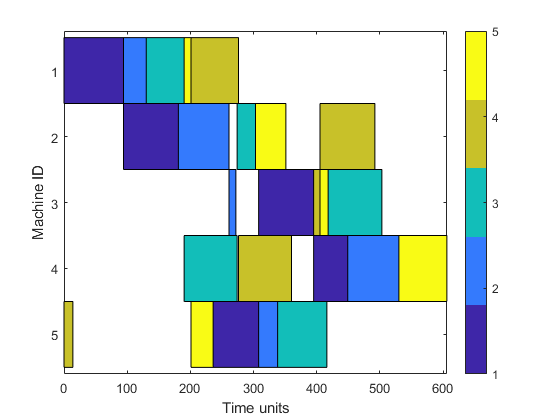


% --- Double check that adequate data are used
HH1.solveInstanceSet(trainInstances1);
HH2.solveInstanceSet(trainInstances1);
HH3.solveInstanceSet(trainInstances1);

% Display solution for a given instance
targetInstance = 3;
HH1.lastSolvedInstances{targetInstance}.solution.plot;

HH2.lastSolvedInstances{targetInstance}.solution.plot;

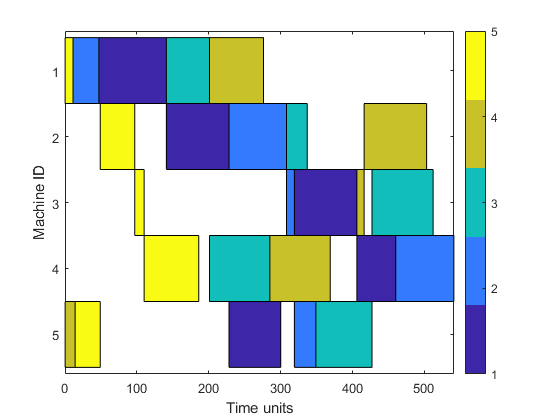

HH3.lastSolvedInstances{targetInstance}.solution.plot;

#### Zones of influence

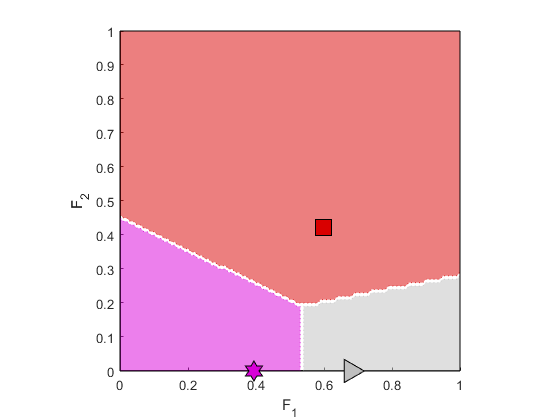

ans =     0.7136       NaN    0.1681    0.1063


% --- Parameters:
points             = 0:0.01:1;
selectedFeatures   = 1:2;
useEuclid          = true; % Use Euclidean distance
doRules            = true; % Plot rules along with zones
% --- Plots:
HH1.plotZones(points, useEuclid, selectedFeatures, doRules)

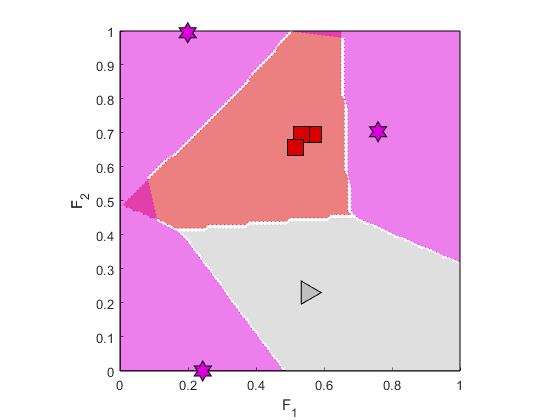

ans =     0.2302       NaN    0.4834    0.2731


HH2.plotZones(points, useEuclid, selectedFeatures, doRules)

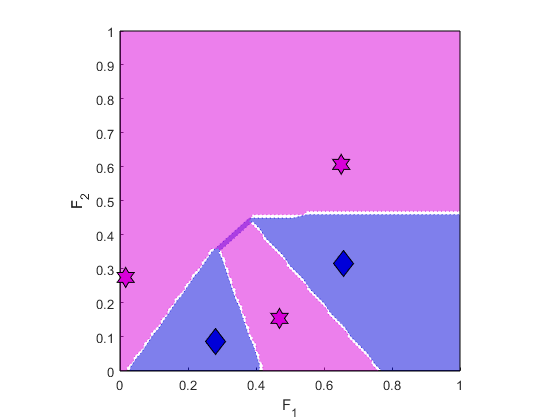

ans =        NaN    0.2701    0.7168


HH3.plotZones(points, useEuclid, selectedFeatures, doRules)

#### Solver usage

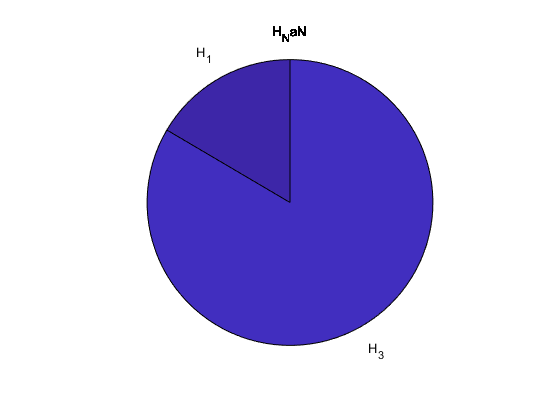

% --- Actual plots
figure, [~, fV1]=HH1.plotSolverUsageDistributionMulti(1:30, true);

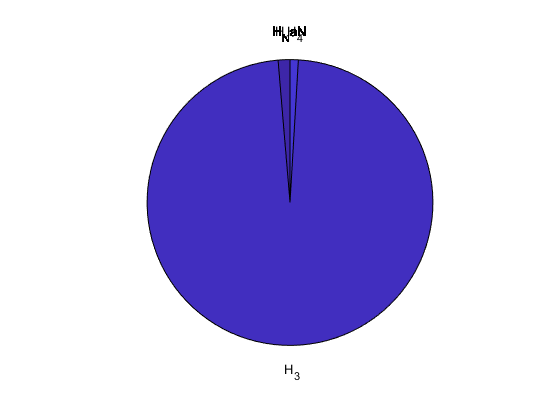

figure, [~, fV2]=HH2.plotSolverUsageDistributionMulti(1:30, true);

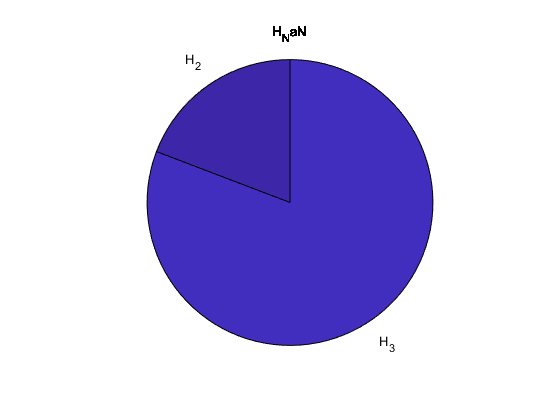

figure, [~, fV3]=HH3.plotSolverUsageDistributionMulti(1:30, true);

#### Solution quality at the given step

In this case we want to determine the distribution of the final solutions:

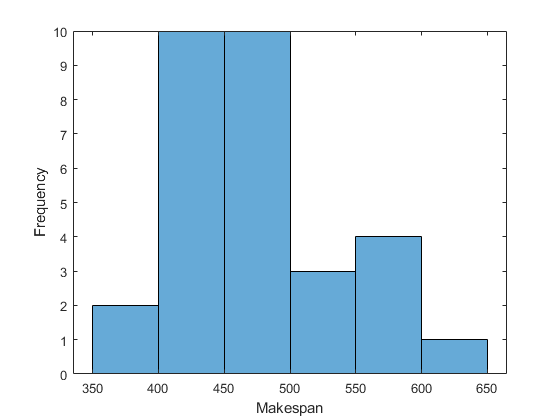

ans =   Axes with properties:

             XLim: [335 665]
             YLim: [0 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure(); HH1.plotStepSolutionDistribution('end')

ans =   Axes with properties:

             XLim: [335 665]
             YLim: [0 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure(); HH2.plotStepSolutionDistribution('end')

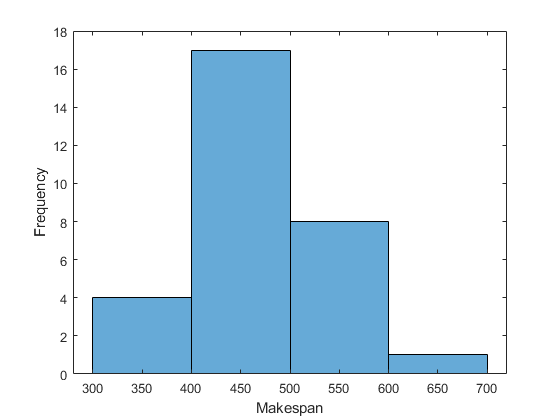

ans =   Axes with properties:

             XLim: [280 720]
             YLim: [0 18]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure(); HH3.plotStepSolutionDistribution('end')